# Sample 9-4

## 離散ウェーブレット変換

縦続接続フィルタバンク

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete wavelet transform

Cascade-structure filter banks

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### リフティング構造フィルタバンク

(Lifting-structure filter banks)

予測ステップと更新ステップで構成されるフィルタバンク (Filter banks consisting of prediction and update steps as follows.)

- 予測ステップ (Prediction step)： $\mathbf{L}_{\mathrm{p}}(z)=\left(\begin{array}{cc} 1 & 0 \\ -P(z)  & 1\end{array}\right)$,$\mathbf{L}_{\mathrm{p}}^{-1}(z)=\left(\begin{array}{cc} 1 & 0 \\ P(z)  & 1\end{array}\right)$

- 更新ステップ (Update step)：$\mathbf{L}_{\mathrm{u}}(z)=\left(\begin{array}{cc} 1 & -U(z) \\0& 1\end{array}\right)$,$\mathbf{L}_{\mathrm{u}}^{-1}(z)=\left(\begin{array}{cc} 1 & U(z) \\0& 1\end{array}\right)$

- 係数シフト(Coefficient delay)：$\mathbf{\Lambda}_\mathrm{b}(z)=\left(\begin{array}{cc} 1 & 0 \\0& z^{-1}\end{array}\right)$, ${\mathbf{\Lambda}}_\mathrm{t}(z)=\left(\begin{array}{cc} z^{-1} & 0 \\0 & 1\end{array}\right)$

予測ステップと更新ステップを縦続接続することで完全再構成フィルタバンクを実現する。(A perfect reconstruction system is realized by connecting the prediction and update steps in cascade.)

なお、(where) $\mathbf{\Lambda}_\mathrm{t}(z)\mathbf{\Lambda}_\mathrm{b}(z)=\mathbf{\Lambda}_\mathrm{b}(z)\mathbf{\Lambda}_\mathrm{t}(z)=z^{-1}\mathbf{I}$ が成立する。(holds.)

【Exampe】9/7-transform adopted in JPEG2000

The length of the analysis filter impluse responses are 9 and 7, respectively.

import msip.ppmatrix

% # of channels
nChs = 2;

% Lifting parameters
alpha = -1.586134342059924;
beta  = -0.052980118572961;
gamma =  0.882911075530934;
delta =  0.443506852043971;
K =  1.230174104914001;

% Delay for low-pass Coefs.
clear topshift
topshift(1,1,2) = 1;
topshift(2,2,1) = 1;
topshift = ppmatrix(topshift);
display(topshift)

topshift = [
	z^(-1),	0;
	0,	1
]


% Delay for high-pass Coefs.
clear btmshift
btmshift(1,1,1) = 1;
btmshift(2,2,2) = 1;
btmshift = ppmatrix(btmshift);
display(btmshift)

btmshift = [
	1,	0;
	0,	z^(-1)
]


分析フィルタバンクの構築 (Conctruction of analysis filter banks)

        
$$\mathbf{E}(z) = \left(\begin{array}{cc}K & 0 \\ 0 & 1/K\end{array}\right)\mathbf{L}_{u,N-1}(z) \mathbf{\Lambda}_\mathrm{t}(z)\mathbf{L}_{p,N-2}(z)\cdots\mathbf{\Lambda}_\mathrm{b} (z)\mathbf{L}_{u,1}(z) \mathbf{\Lambda}_\mathrm{t}(z)\mathbf{L}_{p,0}(z)$$


Gp0 = topshift*predictionstep(alpha);
display(Gp0)

Gp0 = [
	z^(-1),	0;
	-1.5861 - 1.5861*z^(-1),	1
]


Gu1 = btmshift*updatestep(beta);
display(Gu1)

Gu1 = [
	1,	-0.05298 - 0.05298*z^(-1);
	0,	z^(-1)
]


Gp2 = topshift*predictionstep(gamma);
display(Gp2)

Gp2 = [
	z^(-1),	0;
	0.88291 + 0.88291*z^(-1),	1
]


Gu3 = diag([1/K,K])*updatestep(delta);
display(Gu3)

Gu3 = [
	0.81289,	0.36052 + 0.36052*z^(-1);
	0,	1.2302
]


リフティング構造分析フィルタバンクのType-Iポリフェーズ行列 (Type-I polyphase matrix of the analysis filter bank in lifting structure)

E = Gu3*Gp2*Gu1*Gp0;
display(E)

E = [
	0.026749 - 0.078223*z^(-1) + 0.60295*z^(-2) - 0.078223*z^(-3) + 0.026749*z^(-4),	-0.016864 + 0.26686*z^(-1) + 0.26686*z^(-2) - 0.016864*z^(-3);
	0.091272 - 0.59127*z^(-1) - 0.59127*z^(-2) + 0.091272*z^(-3),	-0.057544 + 1.1151*z^(-1) - 0.057544*z^(-2)
]


% Delay chain
dc = delaychain(nChs);
display(dc)

dc = [
	1;
	z^(-1)
]


     分析フィルタ (Analysis filters)

        
$$\mathbf{h}(z) = \left(\begin{array}{c} H_0(z) \\ H_1(z) \\ \vdots \\ H_{M-1}(z) \end{array}\right)
=\mathbf{E}(z^M)\mathbf{d}(z)=\mathbf{E}(z^M)
 \left(\begin{array}{c} 1 \\ z^{-1} \\ \vdots \\ z^{-(M-1)} \end{array}\right)$$


% Analysis filters
h = upsample(E,nChs)*dc;
H = squeeze(double(h))

H =     0.0267   -0.0169   -0.0782    0.2669    0.6029    0.2669   -0.0782   -0.0169    0.0267         0         0         0         0         0         0         0
    0.0913   -0.0575   -0.5913    1.1151   -0.5913   -0.0575    0.0913         0         0         0         0         0         0         0         0         0


合成フィルタバンクの構築 (Construction of synthesis filter bank in lifting structure)

        
$$\mathbf{R}(z) = \mathbf{L}_{p,0}^{-1}(z) \mathbf{\Lambda}_\mathrm{b}(z)\mathbf{L}_{u,1}^{-1}(z)\cdots\mathbf{\Lambda}_\mathrm{t} (z)\mathbf{L}_{p,N-2}^{-1}(z) \mathbf{\Lambda}_\mathrm{b}(z)\mathbf{L}_{u,N-1}^{-1}(z) \left(\begin{array}{cc}1/K & 0 \\ 0 & K\end{array}\right)$$



Giu3 = updatestep(-delta)*diag([K,1/K]);
display(Giu3)

Giu3 = [
	1.2302,	-0.36052 - 0.36052*z^(-1);
	0,	0.81289
]


Gip2 = predictionstep(-gamma)*btmshift;
display(Gip2)

Gip2 = [
	1,	0;
	-0.88291 - 0.88291*z^(-1),	z^(-1)
]


Giu1 = updatestep(-beta)*topshift;
display(Giu1)

Giu1 = [
	z^(-1),	0.05298 + 0.05298*z^(-1);
	0,	1
]


Gip0 = predictionstep(-alpha)*btmshift;
display(Gip0)

Gip0 = [
	1,	0;
	1.5861 + 1.5861*z^(-1),	z^(-1)
]


リフティング構造合成フィルタバンクのType-IIポリフェーズ行列 (Type-II polyphase matrix of the synthesis filter bank in lifting structure)

R = Gip0*Giu1*Gip2*Giu3;
display(R)

R = [
	-0.057544 + 1.1151*z^(-1) - 0.057544*z^(-2),	0.016864 - 0.26686*z^(-1) - 0.26686*z^(-2) + 0.016864*z^(-3);
	-0.091272 + 0.59127*z^(-1) + 0.59127*z^(-2) - 0.091272*z^(-3),	0.026749 - 0.078223*z^(-1) + 0.60295*z^(-2) - 0.078223*z^(-3) + 0.026749*z^(-4)
]


% Delay chain
display(dc.')

[
	z^(-1),	1
]



  合成フィルタ (Synthesis filters)

          
$$\mathbf{f}^T(z) = \left(\begin{array}{cccc} F_0(z) & F_1(z) & \cdots &F_{M-1}(z) \end{array}\right)
=\tilde{\mathbf{d}}(z)\mathbf{R}(z^M)=\left(\begin{array}{cccc} z^{-(M-1)} & z^{-(M-2)} & \cdots & 1 \end{array}\right)\mathbf{R}(z^M)
 $$


% Synthesis filters
f = dc.'*upsample(R,nChs);
F = squeeze(double(f))

F =    -0.0913   -0.0575    0.5913    1.1151    0.5913   -0.0575   -0.0913         0         0         0         0         0         0         0         0         0
    0.0267    0.0169   -0.0782   -0.2669    0.6029   -0.2669   -0.0782    0.0169    0.0267         0         0         0         0         0         0         0


完全再構成条件の確認 (Confirmation of perfect reconstruction)

        
$$\mathbf{R}(z)\mathbf{E}(z)=z^{-N}\mathbf{I} $$
 

display(R*E)

[
	-4.3368e-19 + 6.9389e-18*z^(-1) + 4.1633e-17*z^(-2) + 1*z^(-3) + 6.9389e-17*z^(-4) + 6.9389e-18*z^(-5) - 4.3368e-19*z^(-6),	1.0842e-19 + 1.0842e-19*z^(-5);
	-4.3368e-19 - 3.4694e-18*z^(-1) + 1.3878e-17*z^(-2) - 2.2204e-16*z^(-3) - 2.2204e-16*z^(-4) + 2.7756e-17*z^(-5) - 3.4694e-18*z^(-6) - 4.3368e-19*z^(-7),	z^(-3) + 1.3878e-17*z^(-4)
]



disp(double(R*E))


(:,:,1) =

   1.0e-18 *

   -0.4337    0.1084
   -0.4337         0


(:,:,2) =

   1.0e-17 *

    0.6939         0
   -0.3469         0


(:,:,3) =

   1.0e-16 *

    0.4163         0
    0.1388         0


(:,:,4) =

    1.0000         0
   -0.0000    1.0000


(:,:,5) =

   1.0e-15 *

    0.0694         0
   -0.2220    0.0139


(:,:,6) =

   1.0e-16 *

    0.0694    0.0011
    0.2776         0


(:,:,7) =

   1.0e-17 *

   -0.0434         0
   -0.3469         0


(:,:,8) =

   1.0e-18 *

         0         0
   -0.4337         0


(:,:,9) =

     0     0
     0     0


(:,:,10) =

     0     0
     0     0


(:,:,11) =

     0     0
     0     0


(:,:,12) =

     0     0
     0     0


(:,:,13) =

     0     0
     0     0


(:,:,14) =

     0     0
     0     0


(:,:,15) =

     0     0
     0     0



インパルス応答 (Impluse responses)

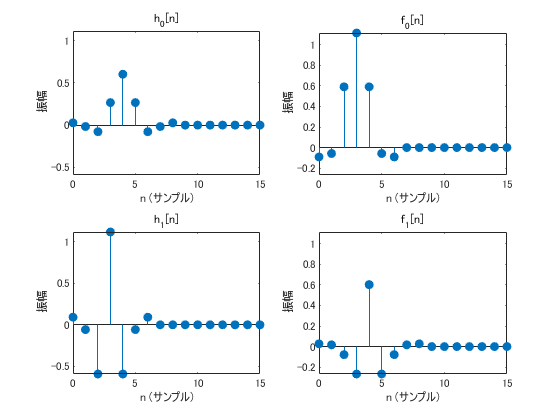

figure(1)
% Low-pass filter
subplot(2,2,1)
impz(H(1,:))
title('h_0[n]')
ax = gca;
ax.YLim =[ min(H(:)) max(H(:)) ];

% High-pass filter
subplot(2,2,3)
impz(H(2,:))
title('h_1[n]')
ax = gca;
ax.YLim =[ min(H(:)) max(H(:)) ];
% Low-pass filter
subplot(2,2,2)
impz(F(1,:))
title('f_0[n]')
ax = gca;
ax.YLim =[ min(F(:)) max(F(:)) ];

% High-pass filter
subplot(2,2,4)
impz(F(2,:))
title('f_1[n]')
ax = gca;
ax.YLim =[ min(F(:)) max(F(:)) ];

周波数応答 (Frequency responses)

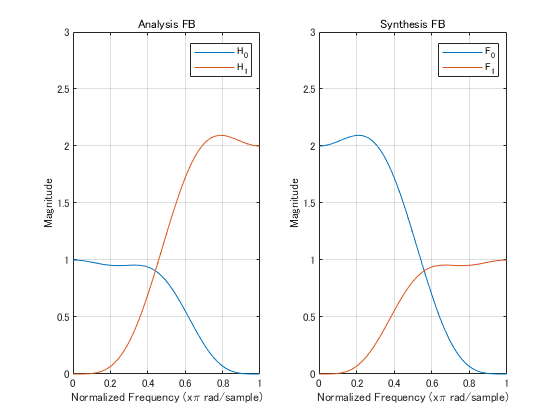

figure(2)
fftPoints = 512;
subplot(1,2,1)
Hfrq = zeros(fftPoints,nChs);
% Low-pass filter
[Hfrq(:,1),W] = freqz(H(1,:),1,fftPoints);
% High-pass filter
Hfrq(:,2) = freqz(H(2,:),1,fftPoints);
plot(W/pi, abs(Hfrq)) %20*log10(abs(F)))
axis([0 1 0 ceil(K*nChs)]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
title('Analysis FB')
legend({ 'H_0', 'H_1' })
grid on
subplot(1,2,2)
Ffrq = zeros(fftPoints,nChs);
% Low-pass filter
[Ffrq(:,1),W] = freqz(F(1,:),1,fftPoints);
% High-pass filter
Ffrq(:,2) = freqz(F(2,:),1,fftPoints);
plot(W/pi, abs(Ffrq)) %20*log10(abs(F)))
axis([0 1 0 ceil(K*nChs)]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
title('Synthesis FB')
legend({ 'F_0', 'F_1' })
grid on

### ラティス構造フィルタバンク

(Lattice-structure filter banks)

回転行列と係数シフトで構成されるフィルタバンク (Filter banks consisting of rotation matrices and coefficient delay)

- 回転行列(Rotation matrix)： $\mathbf{G}_{\theta}=\left(\begin{array}{cc} \cos\theta  & \sin\theta \\ -\sin\theta   & \cos\theta \end{array}\right)$, $\mathbf{G}^{-1}_{\theta}=\left(\begin{array}{cc} \cos\theta  & -\sin\theta \\ \sin\theta   & \cos\theta \end{array}\right)$

- 係数シフト(Coefficient delay)：$\mathbf{\Lambda}_\mathrm{b}(z)=\left(\begin{array}{cc} 1 & 0 \\0& z^{-1}\end{array}\right)$, ${\mathbf{\Lambda}}_\mathrm{t}(z)=\left(\begin{array}{cc} z^{-1} & 0 \\0 & 1\end{array}\right)$

なお、(where) $\mathbf{\Lambda}_\mathrm{t}(z)\mathbf{\Lambda}_\mathrm{b}(z)=\mathbf{\Lambda}_\mathrm{b}(z)\mathbf{\Lambda}_\mathrm{t}(z)=z^{-1}\mathbf{I}$ が成立する。(holds.)

回転行列と係数シフトを縦続接続とすることで完全再構成フィルタバンクを実現する。(A paraunitary (perfect reconstruction) system is realized by connecting rotation matrices and the coefficient shifts in cascade.)

【Example】2-channel orthonormal filter banks (Paraunitary system)

Reference: Table 6.4.1, p.308 in P.P.Vaidyanathan, "**Multirate Systems and Filter Banks,**" Prentice Hall, 1993

import msip.ppmatrix

% # of channels
nChs = 2;
Gtheta = @(theta) [cos(theta)  sin(theta) ; -sin(theta) cos(theta)];

% Lattice parameters
eta = -1; % ∈{-1,1}
thetas = atan([ ...
    -0.2588883e+1 ...
     0.8410785e+0 ...
    -0.4787637e+0 ...
     0.3148984e+0 ...
    -0.2179341e+0 ...
     0.1522899e+0 ...
    -0.1046526e+0 ...
     0.6906427e-1 ...
    -0.4258295e-1 ...
     0.3111448e-1]);

ラティス構造分析フィルタバンクのType-Iポリフェーズ行列 (Type-I polyphase matrix of the analysis filter bank in lattice structure)

        
$$\mathbf{E}(z) = \mathbf{G}_{\theta_{N-1}} \mathbf{\Lambda}_\mathrm{b}(z)\mathbf{G}_{\theta_{N-2}}\cdots\mathbf{\Lambda}_\mathrm{b} (z)\mathbf{G}_{\theta_1} \mathbf{\Lambda}_\mathrm{b}(z)\mathbf{G}_{\theta_0} \left(\begin{array}{cc}1 & 0 \\ 0 & \eta \end{array}\right)$$


E = Gtheta(thetas(1))*diag([1,eta]);
for idx = 2:length(thetas)
    E = Gtheta(thetas(idx))*btmshift*E;
end
display(E)

E = [
	0.22705 + 0.64939*z^(-1) - 0.23234*z^(-2) + 0.11671*z^(-3) - 0.071849*z^(-4) + 0.049755*z^(-5) - 0.036219*z^(-6) + 0.026298*z^(-7) - 0.018511*z^(-8) + 0.018289*z^(-9),	0.5878 + 0.21032*z^(-1) - 0.1761*z^(-2) + 0.12552*z^(-3) - 0.086045*z^(-4) + 0.056409*z^(-5) - 0.034517*z^(-6) + 0.019172*z^(-7) - 0.010528*z^(-8) - 0.0070645*z^(-9);
	-0.0070645 - 0.010528*z^(-1) + 0.019172*z^(-2) - 0.034517*z^(-3) + 0.056409*z^(-4) - 0.086045*z^(-5) + 0.12552*z^(-6) - 0.1761*z^(-7) + 0.21032*z^(-8) + 0.5878*z^(-9),	-0.018289 + 0.018511*z^(-1) - 0.026298*z^(-2) + 0.036219*z^(-3) - 0.049755*z^(-4) + 0.071849*z^(-5) - 0.11671*z^(-6) + 0.23234*z^(-7) - 0.64939*z^(-8) - 0.22705*z^(-9)
]


% Delay chain
dc = delaychain(nChs);
display(dc)

dc = [
	1;
	z^(-1)
]


     分析フィルタ (Analysis filters)

        
$$\mathbf{h}(z) = \left(\begin{array}{c} H_0(z) \\ H_1(z) \\ \vdots \\ H_{M-1}(z) \end{array}\right)
=\mathbf{E}(z^M)\mathbf{d}(z)=\mathbf{E}(z^M)
 \left(\begin{array}{c} 1 \\ z^{-1} \\ \vdots \\ z^{-(M-1)} \end{array}\right)$$


% Analysis filters
h = upsample(E,nChs)*dc;
H = squeeze(double(h))

H =     0.2270    0.5878    0.6494    0.2103   -0.2323   -0.1761    0.1167    0.1255   -0.0718   -0.0860    0.0498    0.0564   -0.0362   -0.0345    0.0263    0.0192   -0.0185   -0.0105    0.0183   -0.0071
   -0.0071   -0.0183   -0.0105    0.0185    0.0192   -0.0263   -0.0345    0.0362    0.0564   -0.0498   -0.0860    0.0718    0.1255   -0.1167   -0.1761    0.2323    0.2103   -0.6494    0.5878   -0.2270


ラティス構造合成フィルタバンクのType-IIポリフェーズ行列 (Type-II polyphase matrix of the synthesis filter bank in lattice structure)

        
$$\mathbf{R}(z) = \left(\begin{array}{cc}1 & 0 \\ 0 & \eta \end{array}\right)\mathbf{A}_{\theta_{0}}^{-1} \mathbf{\Lambda}_\mathrm{t}(z)\mathbf{A}_{\theta_{1}}^{-1}\cdots\mathbf{\Lambda}_\mathrm{t} (z)\mathbf{A}_{\theta_{N-2}}^{-1} \mathbf{\Lambda}_\mathrm{t}(z)\mathbf{A}_{\theta_{N-1}}^{-1}$$


R = diag([1,eta])*Gtheta(-thetas(1));
for idx = 2:length(thetas)
    R = R*topshift*Gtheta(-thetas(idx));
end
display(R)

R = [
	0.018289 - 0.018511*z^(-1) + 0.026298*z^(-2) - 0.036219*z^(-3) + 0.049755*z^(-4) - 0.071849*z^(-5) + 0.11671*z^(-6) - 0.23234*z^(-7) + 0.64939*z^(-8) + 0.22705*z^(-9),	0.5878 + 0.21032*z^(-1) - 0.1761*z^(-2) + 0.12552*z^(-3) - 0.086045*z^(-4) + 0.056409*z^(-5) - 0.034517*z^(-6) + 0.019172*z^(-7) - 0.010528*z^(-8) - 0.0070645*z^(-9);
	-0.0070645 - 0.010528*z^(-1) + 0.019172*z^(-2) - 0.034517*z^(-3) + 0.056409*z^(-4) - 0.086045*z^(-5) + 0.12552*z^(-6) - 0.1761*z^(-7) + 0.21032*z^(-8) + 0.5878*z^(-9),	-0.22705 - 0.64939*z^(-1) + 0.23234*z^(-2) - 0.11671*z^(-3) + 0.071849*z^(-4) - 0.049755*z^(-5) + 0.036219*z^(-6) - 0.026298*z^(-7) + 0.018511*z^(-8) - 0.018289*z^(-9)
]


% Delay chain
display(dc.')

[
	z^(-1),	1
]



  合成フィルタ (Synthesis filters)

          
$$\mathbf{f}^T(z) = \left(\begin{array}{cccc} F_0(z) & F_1(z) & \cdots &F_{M-1}(z) \end{array}\right)
=\tilde{\mathbf{d}}(z)\mathbf{R}(z^M)=\left(\begin{array}{cccc} z^{-(M-1)} & z^{-(M-2)} & \cdots & 1 \end{array}\right)\mathbf{R}(z^M)
 $$


% Synthesis filters
f = dc.'*upsample(R,nChs);
F = squeeze(double(f))

F =    -0.0071    0.0183   -0.0105   -0.0185    0.0192    0.0263   -0.0345   -0.0362    0.0564    0.0498   -0.0860   -0.0718    0.1255    0.1167   -0.1761   -0.2323    0.2103    0.6494    0.5878    0.2270
   -0.2270    0.5878   -0.6494    0.2103    0.2323   -0.1761   -0.1167    0.1255    0.0718   -0.0860   -0.0498    0.0564    0.0362   -0.0345   -0.0263    0.0192    0.0185   -0.0105   -0.0183   -0.0071


完全再構成条件の確認 (Confirmation of perfect reconstruction)

        
$$\mathbf{R}(z)\mathbf{E}(z)=z^{-N}\mathbf{I} $$
 

display(R*E)

[
	8.6736e-19*z^(-1) + 5.2042e-18*z^(-2) - 8.6736e-18*z^(-3) + 3.4694e-18*z^(-4) - 2.4286e-17*z^(-5) + 1.3878e-17*z^(-6) - 4.8572e-17*z^(-7) + 1.3878e-17*z^(-8) + z^(-9) + 1.3878e-17*z^(-10) - 4.8572e-17*z^(-11) + 1.3878e-17*z^(-12) - 2.4286e-17*z^(-13) + 3.4694e-18*z^(-14) - 8.6736e-18*z^(-15) + 5.2042e-18*z^(-16) + 8.6736e-19*z^(-17),	3.4694e-18*z^(-5) + 6.9389e-18*z^(-6) + 5.5511e-17*z^(-8) - 1.3878e-17*z^(-10) + 6.9389e-18*z^(-12) - 3.4694e-18*z^(-13) - 1.7347e-18*z^(-14) - 8.6736e-19*z^(-15);
	-8.6736e-19*z^(-3) - 1.7347e-18*z^(-4) - 3.4694e-18*z^(-5) + 6.9389e-18*z^(-6) - 1.3878e-17*z^(-8) + 5.5511e-17*z^(-10) + 6.9389e-18*z^(-12) + 3.4694e-18*z^(-13),	8.6736e-19*z^(-1) + 1.7347e-18*z^(-2) - 6.9389e-18*z^(-3) + 6.9389e-18*z^(-4) - 2.7756e-17*z^(-5) + 6.9389e-18*z^(-6) - 4.8572e-17*z^(-7) - 2.0817e-17*z^(-8) + 1*z^(-9) - 2.0817e-17*z^(-10) - 4.8572e-17*z^(-11) + 6.9389e-18*z^(-12) - 2.7756e-17*z^(-13) + 6.9389e-18*z^(-14) - 6.9389e-18*z^(-15) + 1.7347e-18*z^(-16) + 8.6736e-19*z^(-

disp(double(R*E))


(:,:,1) =

     0     0
     0     0


(:,:,2) =

   1.0e-18 *

    0.8674         0
         0    0.8674


(:,:,3) =

   1.0e-17 *

    0.5204         0
         0    0.1735


(:,:,4) =

   1.0e-17 *

   -0.8674         0
   -0.0867   -0.6939


(:,:,5) =

   1.0e-17 *

    0.3469         0
   -0.1735    0.6939


(:,:,6) =

   1.0e-16 *

   -0.2429    0.0347
   -0.0347   -0.2776


(:,:,7) =

   1.0e-16 *

    0.1388    0.0694
    0.0694    0.0694


(:,:,8) =

   1.0e-16 *

   -0.4857         0
         0   -0.4857


(:,:,9) =

   1.0e-16 *

    0.1388    0.5551
   -0.1388   -0.2082


(:,:,10) =

    1.0000         0
         0    1.0000


(:,:,11) =

   1.0e-16 *

    0.1388   -0.1388
    0.5551   -0.2082


(:,:,12) =

   1.0e-16 *

   -0.4857         0
         0   -0.4857


(:,:,13) =

   1.0e-16 *

    0.1388    0.0694
    0.0694    0.0694


(:,:,14) =

   1.0e-16 *

   -0.2429   -0.0347
    0.0347   -0.2776


(:,:,15) =

   1.0e-17 *

    0.3469   -0.1735
         0    0.6939


(:

インパルス応答 (Impluse responses)

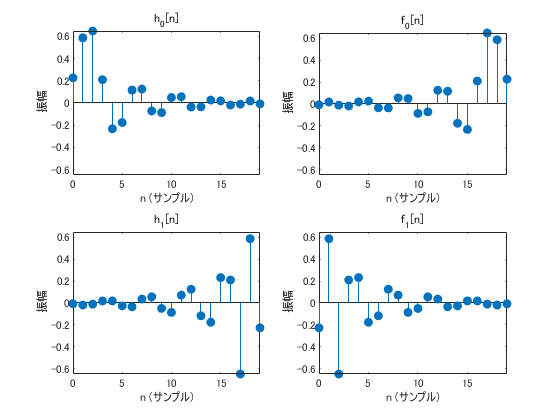

figure(3)
% Low-pass filter
subplot(2,2,1)
impz(H(1,:))
title('h_0[n]')
ax = gca;
ax.YLim =[ min(H(:)) max(H(:)) ];

% High-pass filter
subplot(2,2,3)
impz(H(2,:))
title('h_1[n]')
ax = gca;
ax.YLim =[ min(H(:)) max(H(:)) ];
% Low-pass filter
subplot(2,2,2)
impz(F(1,:))
title('f_0[n]')
ax = gca;
ax.YLim =[ min(F(:)) max(F(:)) ];

% High-pass filter
subplot(2,2,4)
impz(F(2,:))
title('f_1[n]')
ax = gca;
ax.YLim =[ min(F(:)) max(F(:)) ];

周波数応答 (Frequency responses)

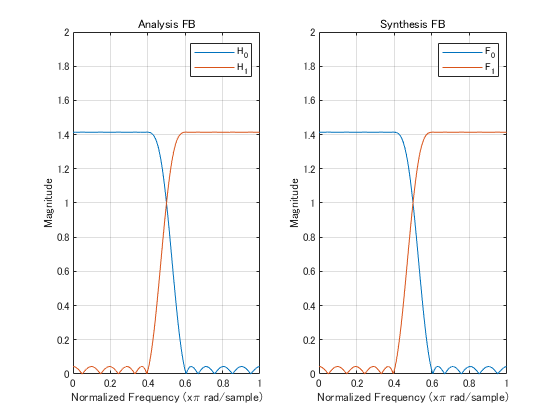

figure(4)
fftPoints = 512;
subplot(1,2,1)
Hfrq = zeros(fftPoints,nChs);
% Low-pass filter
[Hfrq(:,1),W] = freqz(H(1,:),1,fftPoints);
% High-pass filter
Hfrq(:,2) = freqz(H(2,:),1,fftPoints);
plot(W/pi, abs(Hfrq)) %20*log10(abs(F)))
axis([0 1 0 ceil(sqrt(nChs))]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
title('Analysis FB')
legend({ 'H_0', 'H_1' })
grid on
subplot(1,2,2)
Ffrq = zeros(fftPoints,nChs);
% Low-pass filter
[Ffrq(:,1),W] = freqz(F(1,:),1,fftPoints);
% High-pass filter
Ffrq(:,2) = freqz(F(2,:),1,fftPoints);
plot(W/pi, abs(Ffrq)) %20*log10(abs(F)))
axis([0 1 0 ceil(sqrt(nChs))]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
title('Synthesis FB')
legend({ 'F_0', 'F_1' })
grid on

### 関数定義

(Function definition)

function ppm = predictionstep(theta)
    % Prediction step in polyphase matrix
    import msip.ppmatrix
    p(1,1,1) = 1;
    p(2,1,1) = theta;
    p(2,1,2) = theta;
    p(2,2,1) = 1;
    ppm = ppmatrix(p);
end

function ppm = updatestep(theta)
    % Update step in polyphase matrix
    import msip.ppmatrix
    u(1,1,1) = 1;
    u(1,2,1) = theta;
    u(1,2,2) = theta;
    u(2,2,1) = 1;
    ppm = ppmatrix(u);
end

function ppm = delaychain(m)
    % Delay chain
    import msip.ppmatrix
    d = zeros(m,1,m);
    for idx = 1:m
        d(idx,1,idx) = 1;
    end
    ppm = ppmatrix(d);
end

© Copyright, Shogo MURAMATSU, All rights reserved.